clc;
clear;

% Original Matirx
G = [255 255 255 255 255 255 255 255 
255 255 255 255 255 255 255 255 ; 
255 255 255 255 255 255 255 255 ; 
255 255 255 255 255 255 255 255 ; 
255 255 255 255 255 255 255 255 ; 
255 255 255 255 255 255 255 255  
255 255 255 255 255 255 255 255 ; 
255 255 255 255 255 255 255 255 ];

% Using Matlab's inbuilt SVD Function
[U,S,V] = svd(G);
[U1,S1,V1]=svd(G.'); % After rotating G

% Reconstruction of approximate images using largest eigenvalues
img1 = U(:,1)*S(1,1)*V(:,1)';
img2 = U(:,1:2)*S(1:2,1:2)*V(:,1:2)';
img3 = U(:,1:3)*S(1:3,1:3)*V(:,1:3)';
img4 = U(:,1:4)*S(1:4,1:4)*V(:,1:4)';
img5 = U(:,1:5)*S(1:5,1:5)*V(:,1:5)';

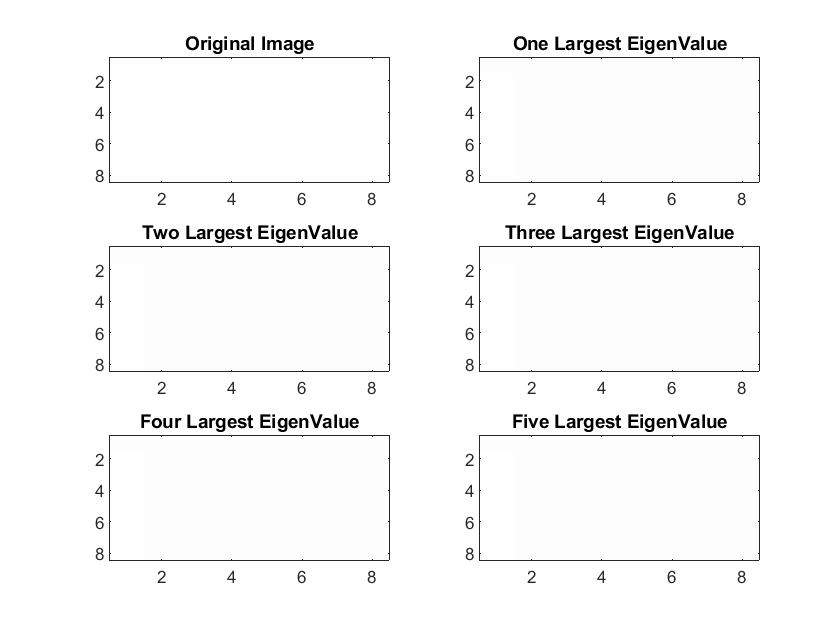

% Plotting the approximate reconstructed images
figure;
subplot(3,2,1);
image(G);
colormap("gray");
title("Original Image");

subplot(3,2,2);
image(img1);
colormap("gray");
title("One Largest EigenValue");

subplot(3,2,3);
image(img2);
colormap("gray");
title("Two Largest EigenValue");

subplot(3,2,4);
image(img3);
colormap("gray");
title("Three Largest EigenValue");

subplot(3,2,5);
image(img4);
colormap("gray");
title("Four Largest EigenValue");

subplot(3,2,6);
image(img5);
colormap("gray");
title("Five Largest EigenValue");

% Getting norm of the difference the original image and reconstructed
% images
dist1=norm(G-img1)

dist1 = 334.0981

dist2=norm(G-img2)

dist2 = 267.8401

dist3=norm(G-img3)

dist3 = 186.5231

dist4=norm(G-img4)

dist4 = 109.0080

dist5=norm(G-img5)

dist5 = 1.5960e-12

diffOnEigenRotated=norm(S-S1)

diffOnEigenRotated = 9.0949e-13